## 1) Load data 

At this stage, you should be able to extract your channel data using the **load_data function. **This function opens your ".mat" exported from Spike2 and stores data from each channel into its own vector. In addition to the sampled data, the time vector for the stimulus channel is stored in the variable *marker*.

% load channel data
[EODOXINGS, AM, AM_dt, vm, vm_dt, marker] = loadNSBdata;

Unable to resolve the name Ch1.values.

Error in loadNSBdata (line 15)
    EOD = Ch1.values;

## 2) Extract spike times from the membrane potential

NOTE: If you extract the spike times before you export from Spike2, you do not need to run this section of code and should skip to the characterization of baseline activity. 

You’ve probably noticed that the membrane potential fluctuates a bit during the recordings, we can take care of this by high-pass filtering the trace. We compare the filtered and unfiltered traces below.

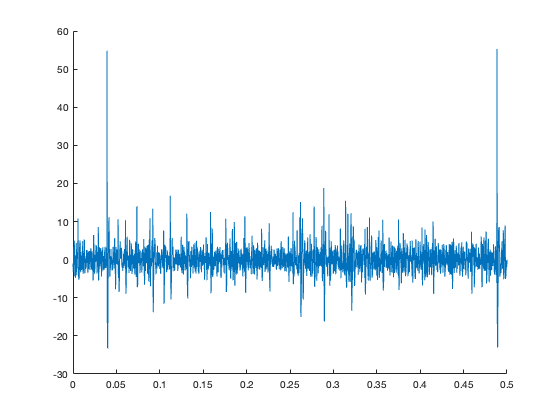

vFs = 1/vm_dt; % The samplerate
% Make a time sequence for the data
    tim = 1/vFs:1/vFs:length(vm)/vFs;
% create a Butterworth filter with 200 Hz cutoff
    [B, A] = butter(2, 200/(vFs/2), 'high');
% filter the membrane potential
    vmfilt = filtfilt(B, A, vm);

% Chose your threshold value based on the filtered data
    figure; hold on; plot(tim(tim < 0.5), vmfilt(tim < 0.5));
    [~, thresh] = ginput(1);

    close(gcf);

% create an empty vector of the length of the data
    Z = zeros(1, length(vmfilt));
% Make every point where the data is above threshold equal to 1 and leave
% everything else as zero
    Z(vmfilt > thresh) = 1;

% Positive zero crossings will have a diff equal to 1   
    indices = find(diff(Z) == 1);

% Convert to seconds
    spiketimes = indices * vm_dt;
    meanSpikeRate = mean(diff(spiketimes));

% and plot
figure; hold on;
    plot(tim, vmfilt, 'b');

    dts = thresh * ones(1,length(spiketimes));
    plot(spiketimes, dts, 'k.', 'MarkerSize', 8);
    xlim([0 30*meanSpikeRate]);

## 3) SAMs: Responses to sinusoidal AMs  

Now look at how receptor afferents (EAs) respond to sinusoidal AMs. 

We’ll be looking for the following: 

- *Are neurons sensitive to different SAM frequencies?*

- *Are neurons sensitive to different SAM amplitudes or, equivalently, are they sensitive to the contrast of the SAM relative to the baseline EOD amplitude? *

To do this, you’ll first need to select the beginning and end times of the SAM at a given frequency (e.g., 2 Hz) (i.e., the trigtimes) and the corresponding spike times. To do so, we’ll first create a binary sequence and then low-pass filter it in order to get an estimate of the instantaneous firing rate. You will then create a phase histogram of the response to the SAM.

NOTE: Load a file in command window with a SAM before running the following code.

**1) Create a binary sequence**

    aFs = 1/AM_dt;
    AMtim = AM_dt:AM_dt:length(AM) * AM_dt; % Time stamps for the AM signal
    
    figure('Visible', "on"); 
    plot(AMtim, AM); % Plot the AM signal over time
    pause;

% Now click slightly before and after the stimulus you want to analyze
% The position of the horizontal line does not matter.

    [X,~] = ginput(2); % Click beginning and end of the stimulus you want to analyze
    close (gcf);
        startime = min(X); 
        endtime = max(X);
        
        AMselected = AM(AMtim > startime & AMtim < endtime);  % AM in range
            newAMtim = 1/aFs:1/aFs:length(AMselected)/aFs;
        spiketimes_selected = spiketimes(spiketimes > startime & spiketimes < endtime); 
            spiketimes_selected = spiketimes_selected - startime;


** Estimate instantaneous firing rate using a low pass filter**

% % Filter the stimulus
%     % 'freqAM' is the SAM frequency (e.g., '2' for a 2 Hz sinewave)
%     freqAM = input('What is the AM frequency?: '); % This is for a filter.
% 
%     [B, A] = butter(2, (freqAM+5) / (1 / (2 * AM_dt)), 'low'); % Up to 5 Hz greater than desired stimulus frequency
%     
%     firingrate_timedependent = filtfilt(B, A, Spikes_selected / AM_dt); % Scale to sample rate
% 
% %plot
%     figure; hold on; box on
%     yyaxis right; plot(AMtim(startindex:endindex), AM_selected)
%     yyaxis left; plot(AMtim(startindex:endindex), firingrate_timedependent);

## **4) SAMs: Phase histogram **

Compute a phase histogram in response to the SAM. To do so, we can threshold the AM sinewave and use these times (i.e., the “trigtimes”) along with “spiketimes_selected” in the function “phase_histogram”  made from the last section. 

*Keep in mind that here “trigtimes” is a time vector that contains the events (in secs) of the stimulus, such as the EOD zero-crossings, or the beginning of one cycle of any other sinusoidal signal. *

% Extract trigger times from SAM stimulus using spikethresh
figure; plot(newAMtim, AMselected);
    pause;
    [~,lvl] = ginput(1);
    close(gcf);

    stimXings = zeros(1,length(newAMtim));
    stimXings(AMselected > lvl) = 1;
    stimXings = diff(stimXings);
    stimXtims = newAMtim(stimXings == 1);

    AMfreq = 1/mean(diff(stimXtims));

% Loop over the spiketimes

    % Trim spiketimes to be earlier than final stimulus cycle
    spiketimes_selected = spiketimes_selected(spiketimes_selected < stimXtims(end));

    AMSpikephase = zeros(1, length(spiketimes_selected)); % Preallocate for speed

    for I = 1:length(spiketimes_selected) % For each spike... 
        ind = find(stimXtims <= spiketimes_selected(I), 1, 'last'); % Get previous EOD zero Xing
        % Phase is 2pi times the ratio [time from EOD crossing prior to spike] / [duration of the EOD crossing to the subseqent]     
        AMSpikephase(I) = 2 * pi * (spiketimes_selected(I) - stimXtims(ind)) / (stimXtims(ind+1) - stimXtims(ind));
    end
 
% Plot phase distribution
    numbins = 30; % Number of bins for the histogram (60 is default)
    PhaseHistedges = linspace(0, 2*pi, numbins);
    PhaseHistbins = histcounts(AMSpikephase, PhaseHistedges);
    titlestr = ['AM freq: ', num2str(round(AMfreq)) ' Hz'];
    figure; box on;  
    bar(PhaseHistedges(2:end), PhaseHistbins);
    xlabel('Radians 2pi')
    ylabel('Spikecounts')
    title(titlestr); 



How does the vector strength vary as a function of frequency? 

## 5) RAMs: Responses to noisy stimuli 

To interperet the responses to RAMs, we first repeat the initial step from the previous section by isolating the spike times and identifying the stimulus epoch. Once we narrow our range to the stimulus event, we can then compute the coherence between the AM and the binary response. 

Load a file with a RAM stimulus and create a binary sequence from the spike times, then select the times at which the noise stimulus begins and ends. 

NOTE: Load a file in command window with a RAM before running the following code.

**1) Create binary sequence**

%% responses to noise
% Time stamps for the AM signal
    AMtim = AM_dt:AM_dt:length(AM) * AM_dt; % Time stamps for the AM signal
   %plot  data
    figure('Visible', "on"); hold on; box on; 
    plot(AMtim, AM);
    pause
    
% Zoom in to the correct part of the graph.
% Then press enter in the command window to resume the program.
%---------------------------------------------------------------------
% Now click slightly before and after the stimulus you want to analyze
% The position of the horizontal line does not matter.

    %select start and end points
    [X,~] = ginput(2);
    close (gcf);
    %assign variables
    starttime = min(X);
    endtime = max(X);
    %convert to indices
    startindex = round(starttime/AM_dt);
    endindex = round(endtime/AM_dt);
    
% Create binary sequency
    SpikeIDX = zeros(length(AM),1);
    
% The binary sequence has the same sampling rate as the AM waveform.
    %Metzen
    SpikeIDX(round(spiketimes/AM_dt)) = 1/AM_dt;
    
    %Eric
    %SpikeIDX(round(spiketimes / AM_dt)) = 1; % Zeros unless a spike happened, then a 1 

    AM_selected = AM(startindex:endindex);  % AM in range
    Spikes_selected = SpikeIDX(startindex:endindex); % Indices relative to AM

    %we don't use this variable... just delete?
    SpikeTimes_selected = spiketimes(spiketimes > starttime & spiketimes <= endtime); % Spike times themselves
    
  
% COHERENCE
% Compute the coherence, which is a number between zero and one.
    [cxy, f] = mscohere(AM_selected, Spikes_selected, bartlett(2048), 1024, 2048, 1/AM_dt);
%plot
    figure; hold on; box on;
    plot(f, cxy);
    xlabel('Frequency (Hz)'); ylabel('Coherence')
    title('Coherence as a function of frequency')

% SPIKE TRIGGERED AVERAGE

## 6) Envelopes: Response to contrast modulated SAMs 

Let’s see if the cells can track the instantaneous stimulus intensity or envelope.

To do this, first threshold the membrane potential in order to get the spike times and binary sequence, then select the appropriate AM epoch, spike times, and binary sequence segment.

NOTE: Load a file in command window with an envelope inducing signal before running the following code.

**1. Extract spike times from membrane potential**

%filter data
% create a Butterworth filter with 200 Hz cutoff
    [B, A] = butter(2, 200/(1/2/vm_dt), 'high');
% filter the membrane potential
    vmfilt = filtfilt(B, A, vm);  
%threshold to extract spike times using spikethresh    
    spiketimes = thresholding(vmfilt, vm_dt);

**2. Generate binary sequence**

% Time stamps for the AM signal
    AMtim = AM_dt:AM_dt:length(AM) * AM_dt; % Time stamps for the AM signal
%plot  data
    figure("Visible", "on"); hold on; box on; 
    plot(AMtim, AM);
    pause
    
% Zoom in to the correct part of the graph.
% Then press enter in the command window to resume the program.
%---------------------------------------------------------------------
% Now click slightly before and after the stimulus you want to analyze
% The position of the horizontal line does not matter.

    %select start and end points
    [X,~] = ginput(2);
    close (gcf);
    %assign variables
    starttime = min(X);
    endtime = max(X);
    %convert to indices
    startindex = round(starttime/AM_dt);
    endindex = round(endtime/AM_dt);
    
%create binary sequency
    SpikeIDX = zeros(length(AM),1);
% the binary sequence has the same sampling rate as the AM waveform.
    %Metzen
    %SpikeIDX(round(spiketimes/AM_dt)) = 1/AM_dt;
    
    %Eric
    SpikeIDX(round(spiketimes / AM_dt)) = 1; % Zeros unless a spike happened, then a 1 

    AM_selected = AM(startindex:endindex);  % AM in range
    Spikes_selected = SpikeIDX(startindex:endindex); % Indices relative to AM


**3. Calculate envelope response**

env = abs(hilbert(AM_selected - mean(AM_selected)));
[B, A] = butter(4, 1/(1/2/AM_dt));
firingrate_timedependent = filtfilt(B, A, Spikes_selected - 0.5);

figure; hold on; box on;
yyaxis right; plot(AMtim(startindex:endindex), filtfilt(B, A, env - mean(env)))
yyaxis left; plot(AMtim(startindex:endindex), firingrate_timedependent);

Does the firing rate track the envelope? Try looking at this under different conditions (i.e., for different stimulus intensities). 